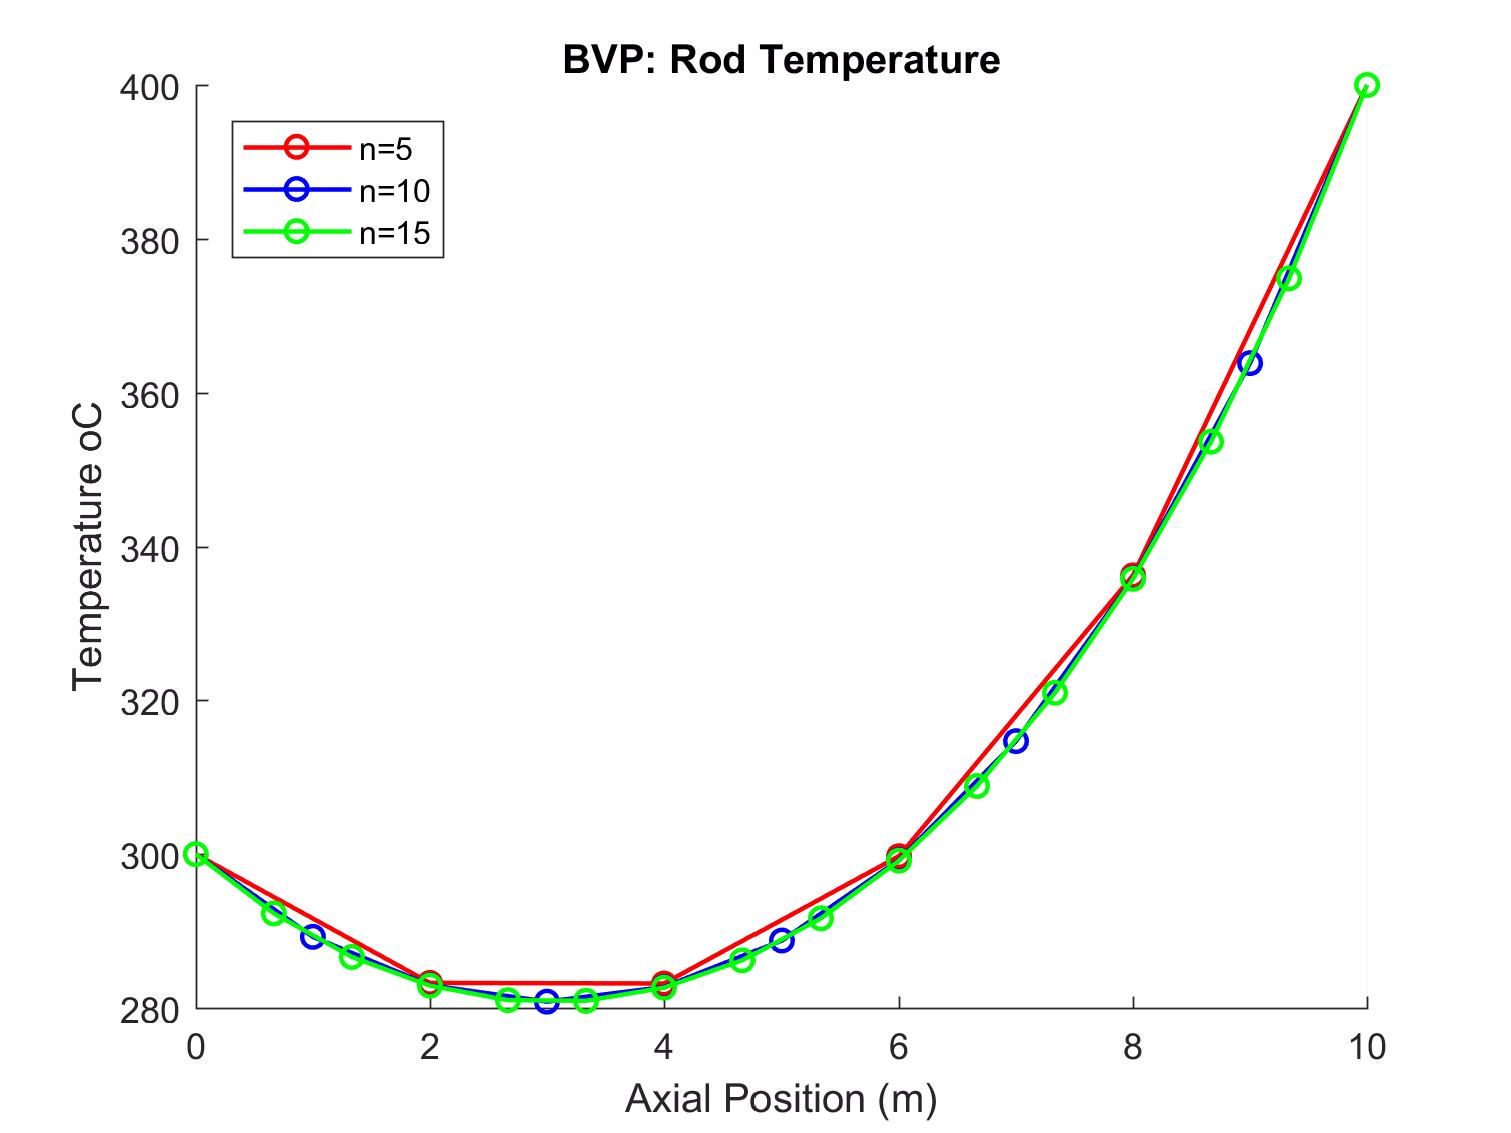

lowerB = 300; upperB = 400;
N1 = 5; N2 = 10; N3 = 15;

[matrixXN1, x1] = sysLinEq(lowerB, upperB, N1);
[matrixXN2, x2] = sysLinEq(lowerB, upperB, N2);
[matrixXN3, x3] = sysLinEq(lowerB, upperB, N3);

hold on
plot(x1, matrixXN1, '-or', 'LineWidth', 1.25);
plot(x2, matrixXN2, '-ob', 'LineWidth', 1.25);
plot(x3, matrixXN3, '-og', 'LineWidth', 1.25);
hold off
title('BVP: Rod Temperature');
xlabel('Axial Position (m)');
ylabel('Temperature oC');
legend('n=5','n=10','n=15','Location','NorthWest');

function [matrixX, x] = sysLinEq(lowerB, upperB, n)
matrixB = zeros(n-1, 1);

delta = (10-0)/n;
x = 0:delta:10;

%matrixA
a(1:n-1) = -((2/(delta)^2) + 0.05);
b(1:n-2) = (1/(delta^2));
matrixA1 = diag(a);
matrixA2 = diag(b, -1);
matrixA3 = diag(b, 1);

matrixA = matrixA1 + matrixA2 + matrixA3;

%matrixB
matrixB(1) = -10-(1/(delta^2))*(lowerB);
matrixB(end) = -10-(1/(delta^2))*(upperB);
for i = 2:n-2
    matrixB(i) = -10;
end
%matrixX
matrixX = matrixA \ matrixB;
matrixX = [300; matrixX; 400];

end

